## 2.3 Hopfield Networks

The synaptic connections between the neurons of a Hopfield network constitute a symmetrically weighted complete graph.

In a Hopfield network of binary (ON/OFF) neurons, the states of the neurons are updated sequentially in random order. The update rule is very simple, if the total input to the neuron exceeds a threshold (usually zero) the neuron is set to on, otherwise it is set to off.

**Note that weights very well can be negative or equivalently, that the synapses can be inhibitory.**

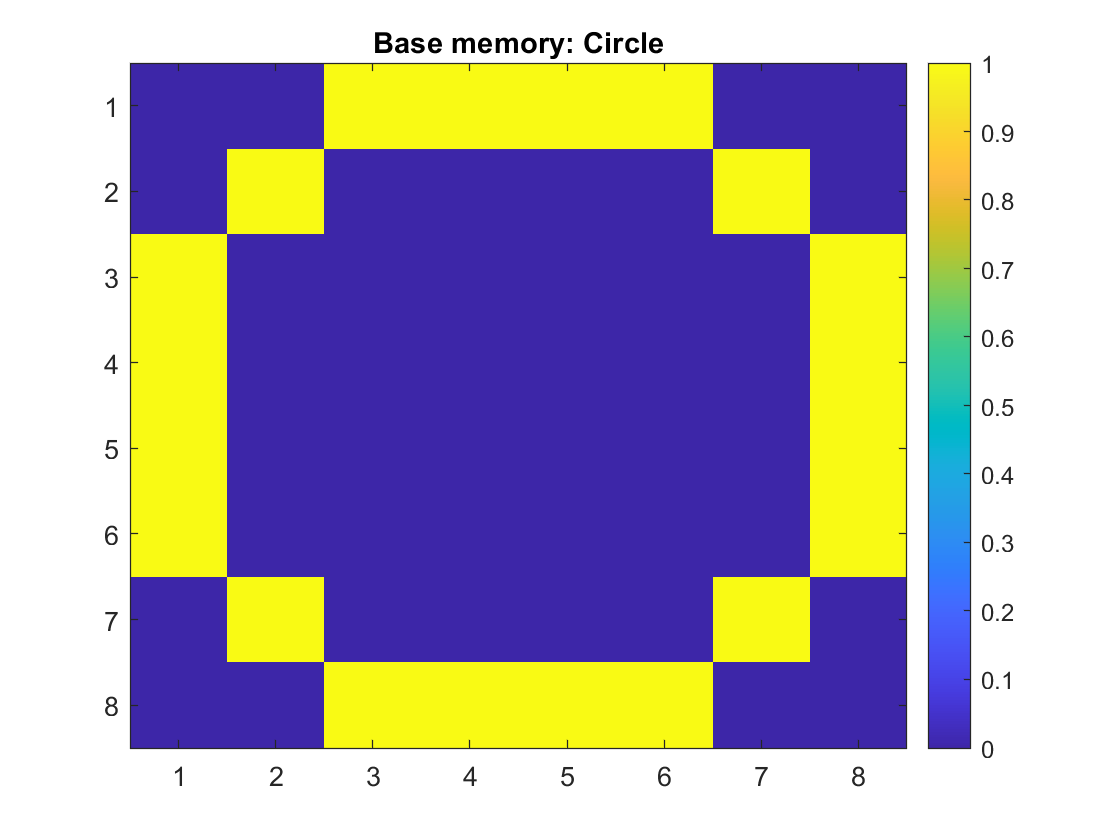

clear all;

% Import images as an matrix with values between 0 and 1
img_cir = rgb2gray(imread('Images/circle.png')) / 255;
img_squ = rgb2gray(imread('Images/square.png')) / 255;
img_tri = rgb2gray(imread('Images/triangle.png')) / 255;
img_cre = rgb2gray(imread('Images/crecent.png')) / 255;

% Print memories
image(img_cir,'CDataMapping','scaled')
title("Base memory: Circle")
colorbar

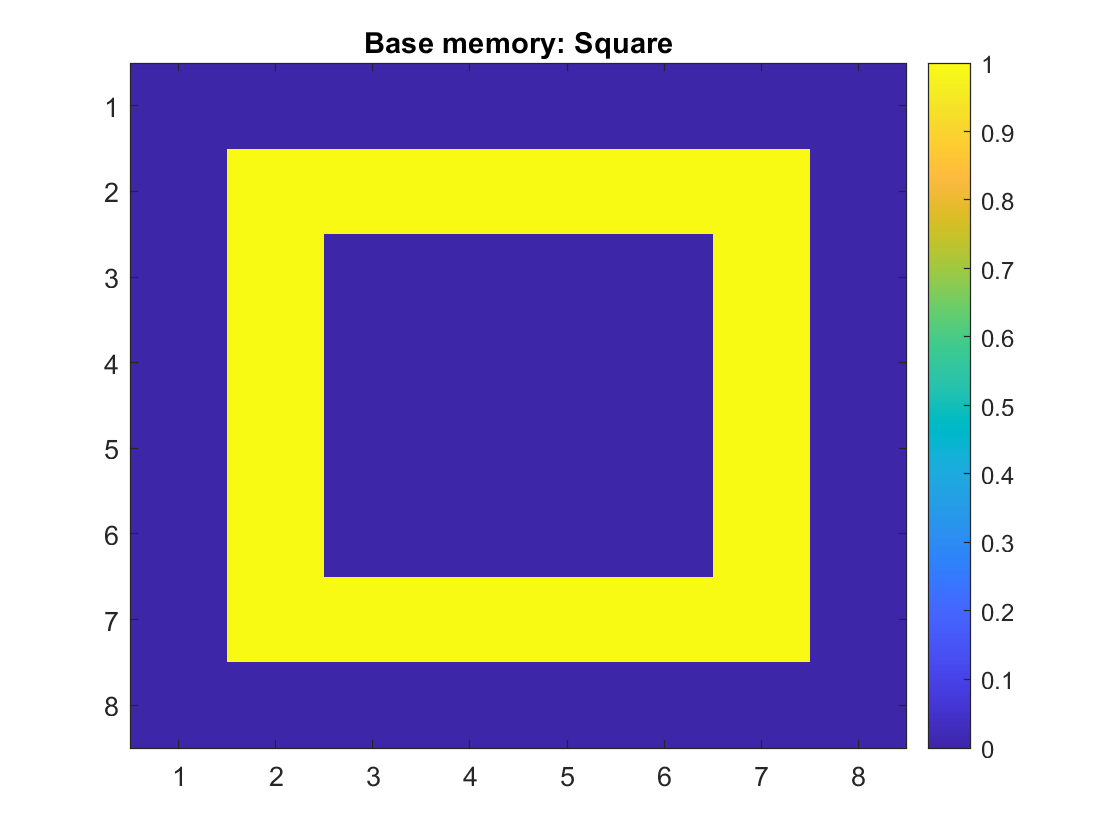

image(img_squ,'CDataMapping','scaled')
title("Base memory: Square")
colorbar

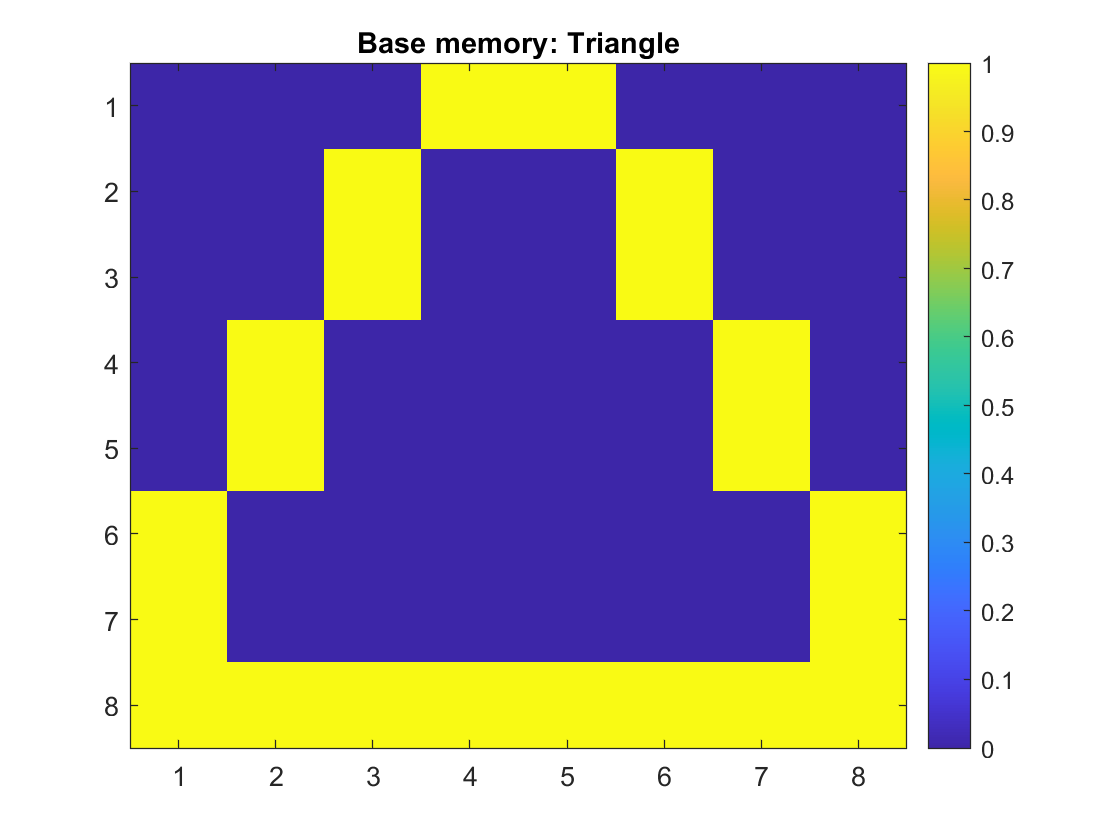

image(img_tri,'CDataMapping','scaled')
title("Base memory: Triangle")
colorbar

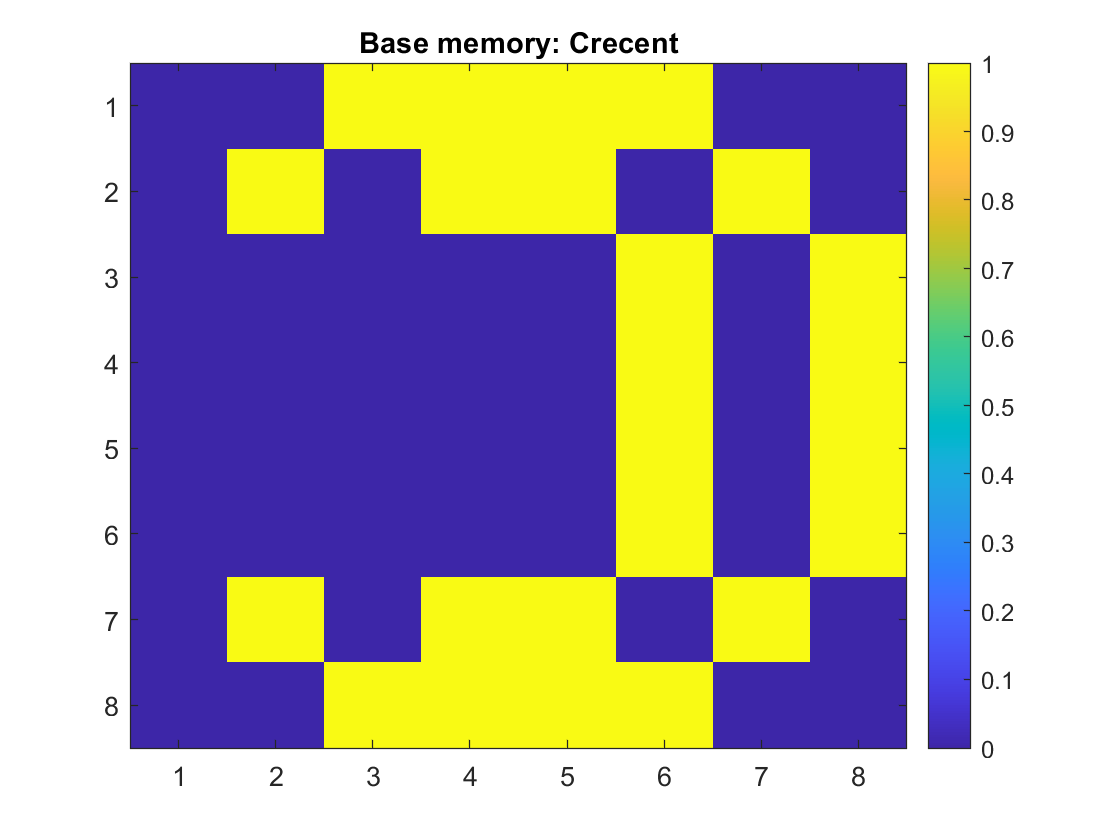

image(img_cre,'CDataMapping','scaled')
title("Base memory: Crecent")
colorbar


% Rescale the matrices to vectors
Memories.cir = reshape(img_cir,1,[]);
Memories.squ = reshape(img_squ,1,[]);
Memories.tri = reshape(img_tri,1,[]);
%Memories.cre = reshape(img_cre,1,[]);

### **2.3.1 Storing memories / Generating weight matrix**

Given that we use 1 and 0:


$$w_{\textrm{ij}} =\frac{1}{|M|}\sum_{m\in M} 4\left(m_i -\frac{1}{2}\right)\left(m_j -\frac{1}{2}\right)$$


Given that we use 1 and -1:


$$w_{\textrm{ij}} =\frac{1}{|M|}\sum_{m\in M} m_i m_j$$


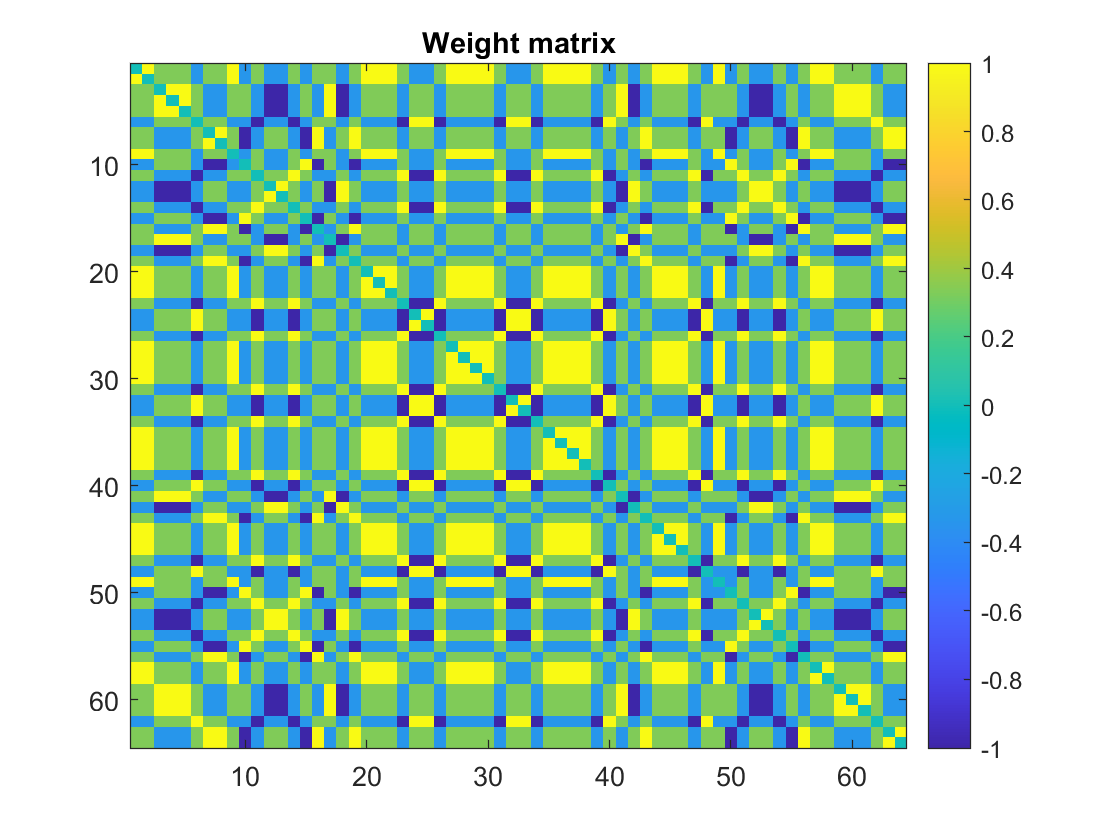

% Define weight matrix
W = zeros(64,64);

% For each memory we want to store in the network
mem_names = fieldnames(Memories);
for idx = 1:numel(mem_names)
    % Compute its inpact on the weigth values:
    mem_vec = double(Memories.(mem_names{idx}));
    W = W + 4 * (mem_vec' - 0.5) * (mem_vec - 0.5);
end

% Normalise W by the amount of memories
W = W / numel(mem_names);

% Remove self connections (diagonal)
W = W - eye(64);

image(W,'CDataMapping','scaled')
title("Weight matrix")
colorbar

### 2.3.x Processing / Simulating the binary hopfield network

Have an initial condition (perterbed image) and update neurons at random.

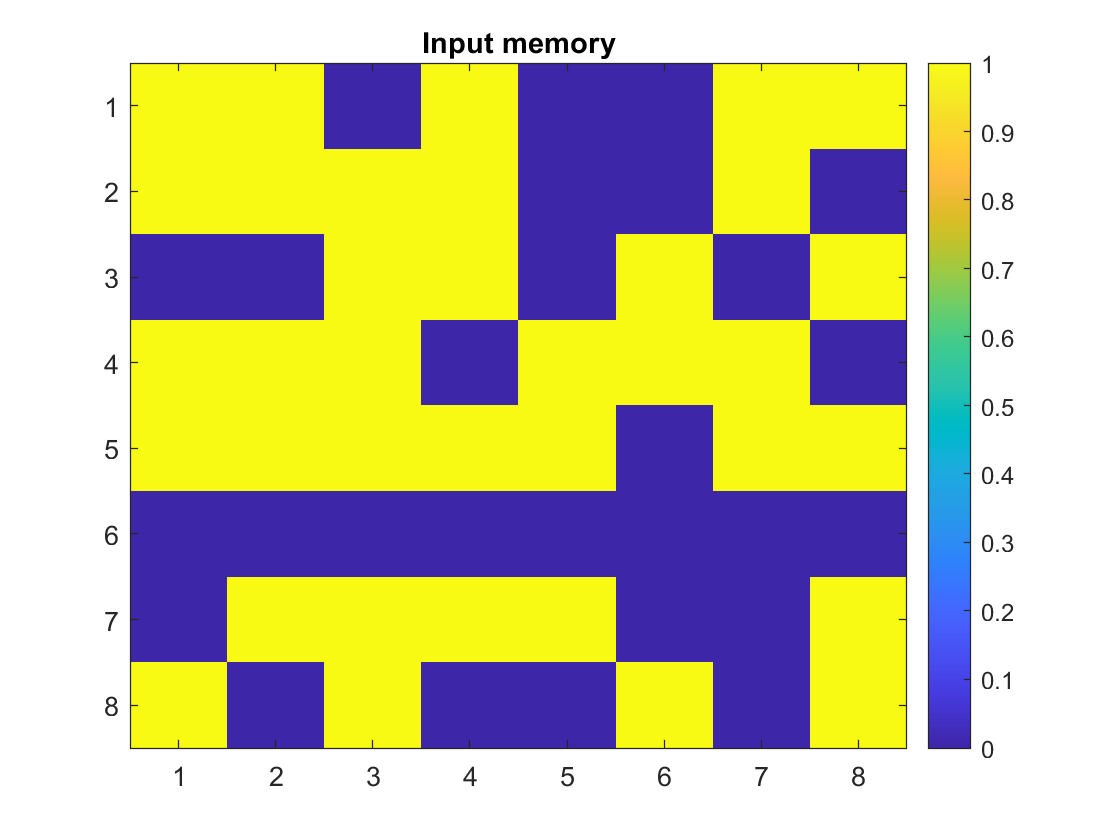

% Define initial state
%x = zeros(1,64);
%x(10:15) = ones(1,6);
%x(50:55) = ones(1,6);
x = randi(2,[1 64]) - 1;
image(reshape(x,8,8),'CDataMapping','scaled')
title("Input memory")
colorbar

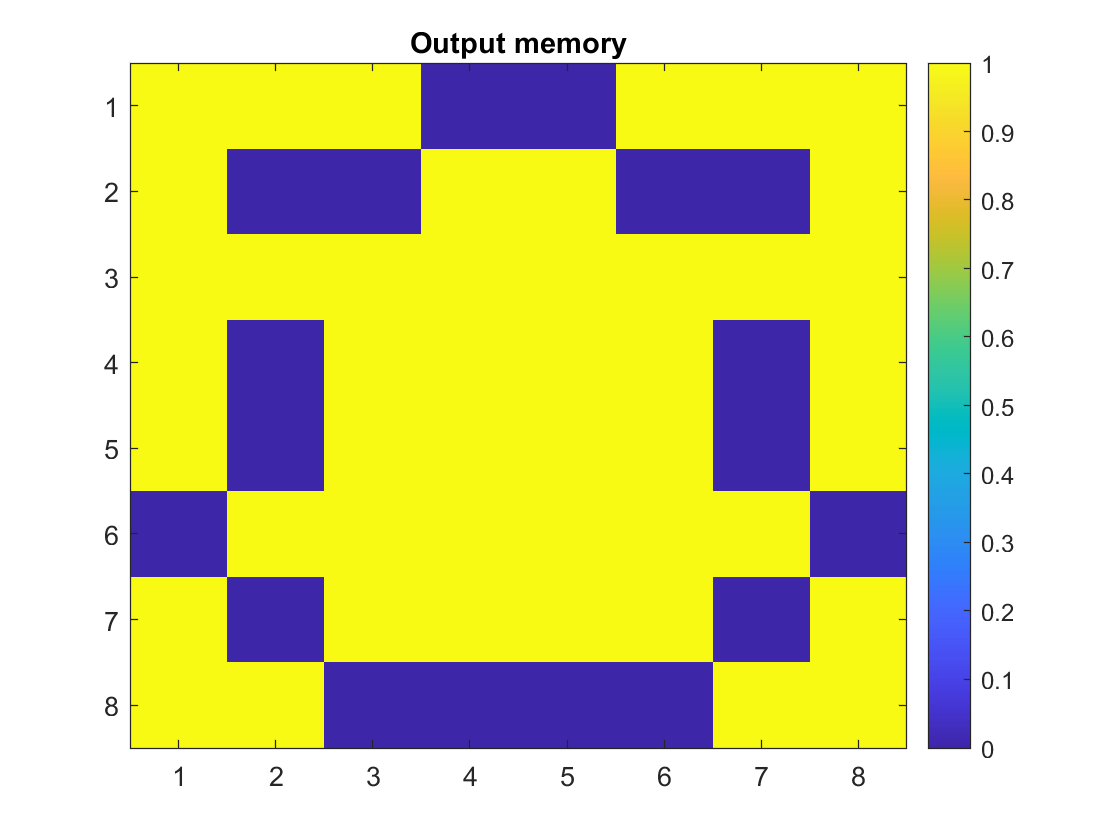


% Return an array with all energys present at all nodes
energy_at_nodes = @(x, W) sum((W.*x'));
global_energy = @(x, W) sum(energy_at_nodes(x,W) .* x) / 2;

% Define number of iterations
iter = 1000;

% Debug variables
ge_arr = zeros(1,iter);
ge_arr(1) = global_energy(x,W);

% For the given number of iterations:
for idx = 2:iter
    % Pick a random node
    rand_node = randi(64);
    
    % Compute the energy present at each node
    en_arr = energy_at_nodes(x,W);
    
    % Update the randomly picked node
    if (en_arr(rand_node) > 0)
        x(rand_node) = 1;
    else
        x(rand_node) = 0;
    end
    
    % Debug Collect global energy at each time step
    ge_arr(idx) = global_energy(x,W);
end

% Print final result
image(reshape(x,8,8),'CDataMapping','scaled')
title("Output memory")
colorbar

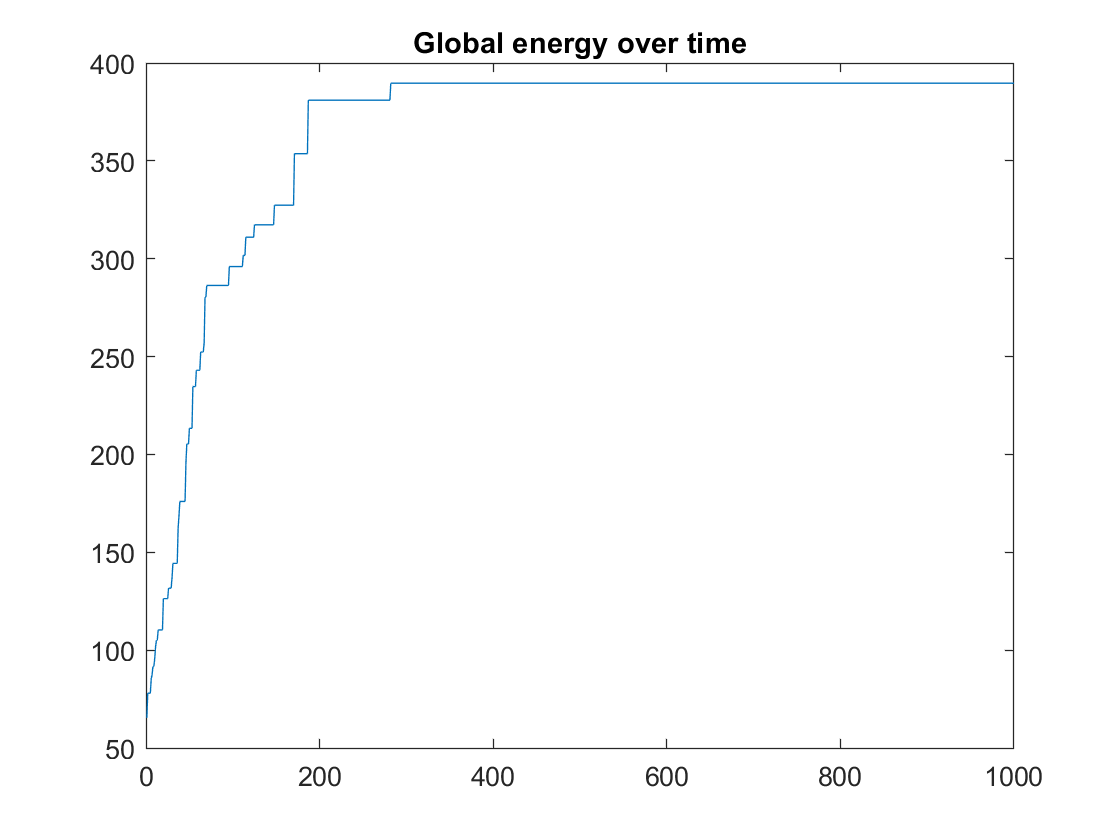

plot(1:iter, ge_arr)
title("Global energy over time")